# PODSTAWY PROGRAMOWANIA W JĘZYKU MATLAB

## Rysowanie wykresów w MATLAB

Opracował: K. Król

**---------------------------------------------------------------------------------------------------------------------------------------------**

**UWAGA! Zaleca się pracować z niniejszym skryptem ustawiając opcję "View" -> "Output on Rigth"**

**---------------------------------------------------------------------------------------------------------------------------------------------**

W trakcie laboratorium będziesz bardzo często rysował wykresy różnych zależności numerycznych. Przykład rysowania błędu w funkcji kroku, bądź kolejnych iteracji, omawialiśmy ogólnie w module dotyczącym pętli. Tutaj powiemy sobie, w bardzo dużym stopniu ogólności, jak działa wykreślanie podstawowych wykresów w MATLAB. Trzeba jednak wspomnieć, że mechanizm obsługi grafiki w MATLAB jest dosyć skomplikowany i jego omówienie w ramach tych zajęć wykracza zdecydowanie poza możliwe ramy czasowe. Dlatego pewne rzeczy będziesz musiał przyjąć 'na wiarę'.

W ramach WNUM będziemy stosować najprostszą metodę rysowania polegającą na stworzeniu dwóch wektorów - jednego reprezentującego współrzędne X i drugiego współrzędne Y punktów, które mają być narysowane.

Wszystkie funkcje rysujące, o których będziemy mówić, przyjmują jako argument wejściowy te dwa wektory. Przykładowo:

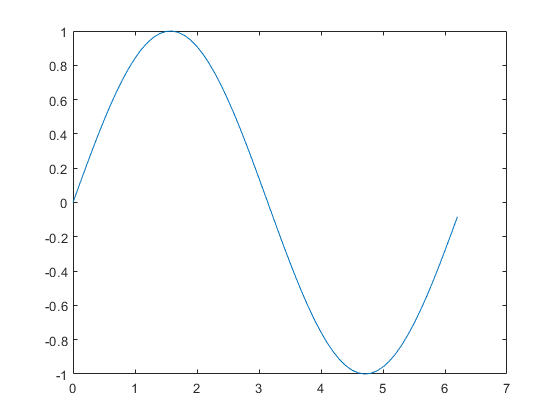

x = [0:0.1:2*pi];

y = sin(x);

% Podstawową funkcją rysującą jest funkcja plot()

plot(x,y)

W efekcie powstaje wykres znajdujący się na osobnym oknie. Wykres zostanie domyślnie wrysowany w aktywne okno graficzne (jeżeli jest otwarte kilka takich okien), oraz nadpisze dane, które się tam znajdują.

Okna graficzne w MATLAB możemy tworzyć komendą ***figure()***. Wywołana bez argumentów stworzy nowe okno i ustawi je jako aktywne. Wywołana z numerem wybierze okno o zadanym numerze lub stworzy takie okno, jeżeli go jeszcze nie ma:

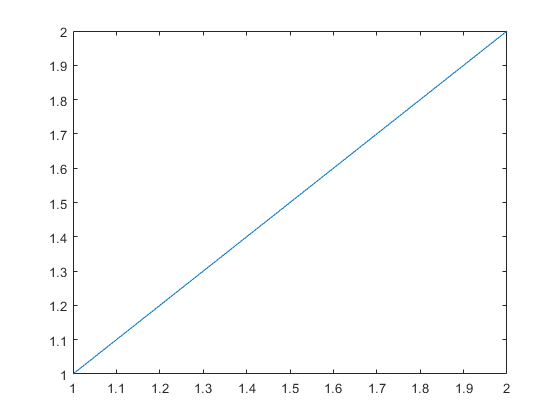

% Przykład wykorzystania komendy figure()

% Skopiuj ten kod do osobnego skryptu. W Live Script komenda figure jest
% ignorowana (wyjście graficzne jest przechwytywane przez inny mechanizm
% obsługi grafiki niż domyślny). Uruchamiaj kod sekcjami

figure()   % tworzy nowe okno

%% Jeżeli wywołamy tę komendę z numerem

figure(1)
figure(2)
plot([1 2], [1 2]);


%% Ponowne wywołanie okna 1 ustawi je jako aktywne(widoczne na wierzchu) o
% ile okno już istnieje

figure(1)

Error using plot
Line cannot be a child of Figure.

## Problem skali

W trakcie realizacji WNUM będziesz często miał do czynienia z problemem rysowania w odpowiedniej skali. Komenda ***plot()*** rysuje wykresy w skali liniowej. Taki wykres nie nadaje się do przedstawiania wielu zależności występujących na WNUM, w szczególności zależności błędów, które nierzadko zmieniają się o wiele rzędów wielkości. Przykładowo:

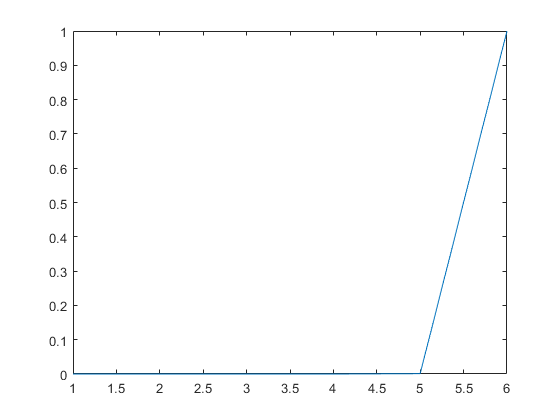

x = [1 2 3 4 5 6];
blad = [1e-13 1e-11 1e-9 1e-6 1e-3 1];

plot(x, blad);


% Zwróć uwagę, że wykres wygląda jakby był efektem błędu (prawie pionowa
% linia). W skali liniowej nie widać w ogóle tego, jak taka
% zależność wygląda, bo większość danych jest dużo mniejsza od 1.
 

Aby narysować wykres wykorzystujący skalę logarytmiczną należy użyć komend:

- ***semilogx()*** - tworzy wykres, w którym oś OX jest logarytmiczna a OY liniowa,

- ***semilogy()*** - tworzy wykres, w którym oś OX jest liniowa a OY logarytmiczna,

- ***loglog()*** - tworzy wykres, w którym obie osie są logarytmiczne.

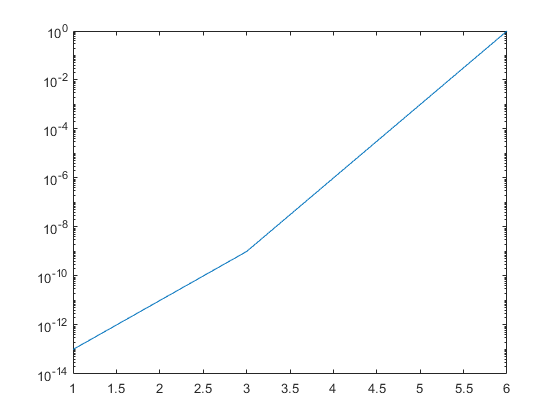

% Dobór komendy powinien odbywać się na podstawie danych
% W naszym przykładzie mamy praktycznie liniowo zmieniające się wartości na
% osi OX i zmieniające się o wiele rzędów wielkości wartości na osi OY, zatem:
x = [1 2 3 4 5 6];

blad = [1e-13 1e-11 1e-9 1e-6 1e-3 1];

semilogy(x, blad);

% Taki wykres jest znacznie czytelniejszy

 

## Formatowanie wykresów liniowych

Podobnie jak wszystkie funkcje graficzne MATLAB mogą przyjmować opcjonalny argument wejściowy w postaci uchwytu funkcji, wszystkie przyjmują również opcjonalny argument w postaci tekstu (ciągu typu string) opisującego formatowanie graficzne rysowanej linii. Argument ten może być podany oddzielnie po każdej serii danych. Mamy tutaj następujące możliwości:

**Styl linii**

`-    Linia ciągła`

`--   Linia przerywana`

`:    Linia kropkowana`

**Styl znacznika punktu**

`o          Kółko`

`*          Gwiazdka`

`x          Krzyżyk`

`d          Karo`

`^, v, >, < Różne trójkąty`

**Kolor**

`y            żółty`

`m            `magenta

`c            `cyan

`r            czerwony`

`g            zielony`

`b            niebieski`

`k            czarny`

Więcej informacji i składowych "stringu" formatującego znajdziesz w dokumentacji dowolnej z funkcji rysujących, choć taki zestaw w zupełności wystarcza do zrobienie laboratoriów z WNUM. Ciąg należy umieścić w pojedynczych cudzysłowach. 

Przykładowo:

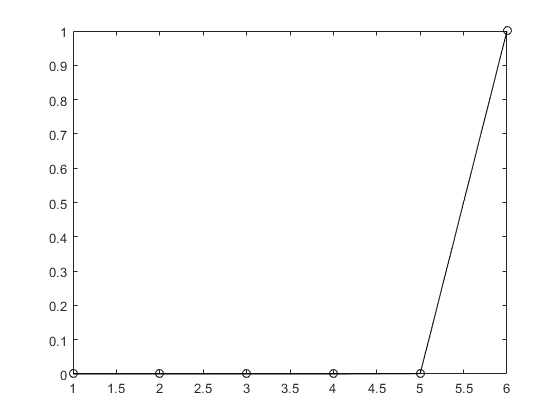

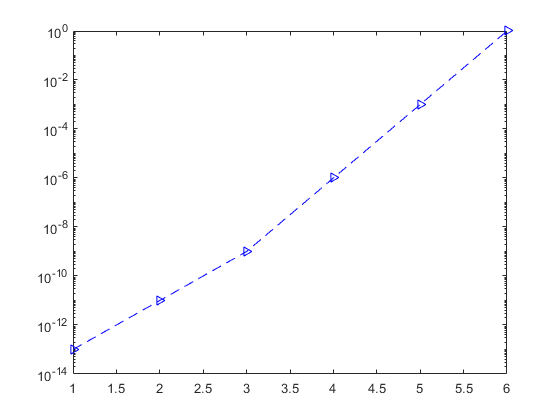

x = [1 2 3 4 5 6];

blad = [1e-13 1e-11 1e-9 1e-6 1e-3 1];

figure(1)
plot(x, blad, 'ko-');

figure(2)
semilogy(x, blad, 'b>--');

% Zwróć uwagę, że zaznaczając znaczniki od razu widać czy wykres jest w
% dobrej skali w stosunku do danych

 

## RYSOWANIE WIELU WYKRESÓW W JEDNYM OKNIE I PODSTAWOWE FORMATOWANIE WYKRESÓW

Domyślnie narysowanie nowego wykresu w istniejącym oknie graficznym nadpisuje dotychczasowy rysunek. Czasami jednak zachodzi potrzeba 'dorysowywania' kolejnych wykresów na jednym układzie współrzędnych. Służy do tego przełącznik ***hold***. 

Ta i inne komendy opisane w tym rozdziale mają specyficzne działanie. Sterują one obiektem graficznym w MATLAB ustawiając jego właściwości. Obiekty graficzne istnieją poza przestrzenią danych konsoli/funkcji w osobnej przestrzeni danych mechanizmu zarządzania grafiką. Ustawienie jakiejś właściwości obiektu graficznego jest trwałe, dopóki ten obiekt istnieje, albo nie zostanie ona znowu mieniona. W szczególności:

- Obiekty graficzne nie są usuwane, ani czyszczone po zakończeniu wykonywania skryptu lub funkcji, w której zostały utworzone chyba, że jest to jawnie zaprogramowane w kodzie użytkownika. Dlatego jeden obiekt graficzny może istnieć z niezmienionymi właściwościami w trakcie niejednego wywołania skryptu/funkcji.

- Obiekty graficzne mogą być usunięte niezależnie od kodu użytkownika (np. okno graficzne może zostać w dowolnej chwili zamknięte przy pomocy wskaźnika myszy). Ponowne jego stworzenie ustawi wszystkie właściwości na wartości domyślne niezależnie od poprzednich ustawień (nawet w trakcie działania jednego skryptu).

Przydatne funkcje i przełączniki działające w ten sposób:

- ***hold on***                  - powoduje, że każda kolejna próba zapisu wykresu do okna spowoduje jego dodanie bez usuwania poprzednich wykresów

- ***hold off***                  - efekt odwrotny do powyższego

- ***grid on ***                  - spowoduje wyświetlanie linii siatki w oknie wykresu

- ***grid off ***                  - efekt odwrotny do powyższego

- ***title(<string>) ***        - ustawi tytuł okna wykresu

- ***xlabel(<string>), ylabel(<string>)*** - ustawia podpisy osi okna graficznego

- ***legend(<string>, <string>, ...)*** - wyświetla legendę z opisem podanym wg kolejności dodania wykresów do okna graficznego.

- ***yyaxis left/rigth***      - przełącza rysowanie pomiędzy osiami lewą i prawą

% Przykład:
x = [1 2 3 4 5 6];

mnoznik = 1

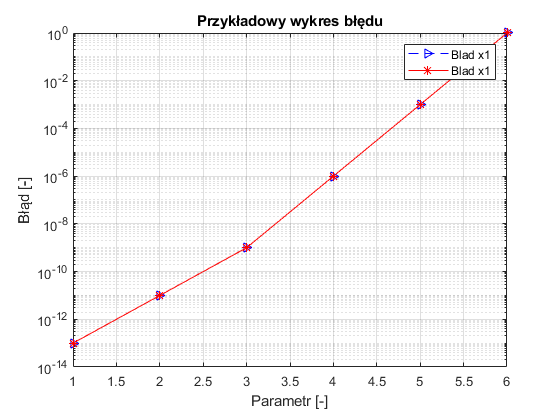

blad = [1e-13 1e-11 1e-9 1e-6 1e-3 1];

mnoznik = 1

figure(2)
%yyaxis left
semilogy(x, blad, 'b>--');

grid on;
title('Przykładowy wykres błędu');
xlabel('Parametr [-]');
ylabel('Błąd [-]');

hold on


%yyaxis right
semilogy(x, mnoznik*blad, 'r*-');
legend('Blad x1', ['Blad x' num2str(mnoznik)]);

% Uruchom ten skrypt jeszcze raz ale z inną wartością zmiennej 'mnoznik'. Jak
% widzisz wykresy dalej się dorysowują. Teraz odkomentuj poniższą linijkę i
% wykonaj kilka razy skrypt

%hold off

% Na koniec odkomentuj przełączniki yyaxis i zobacz jak teraz działa kod. 

 

## Inne sposoby na rysowanie wielu wykresów w jednym oknie

Omówiony w poprzedniej sekcji sposób rysowania wielu wykresów w jednym oknie orientował wszystkie punkty do tych samych osi (z ewentualnym wykorzystaniem przełącznika yyaxis). Można jednak wrysowywać w okno graficzne wiele osi. Jednym ze sposób aby to zrobić jest komenda:

**tiledlayout(m,n)**

gdzie m to ilość wierszy osi a n to ilość kolumn osi. Zalecam korzystanie z układu 2x1 bo wtedy pokrywają się osie OX, ewentualnie układu 1x2 - pokrywają się osie OY. Większe zbiory osi są często nieczytelne.

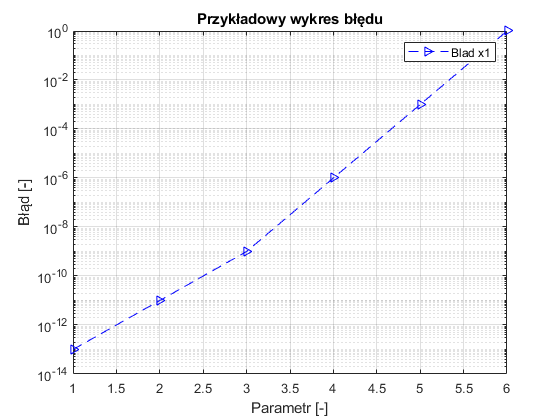

% Przykład - efekt słabo widoczny w LiveScript ze względu na
% przechwytywanie grafiki. Zaleca się skopiowanie do osobnego m-pliku.
x = [1 2 3 4 5 6];
blad = [1e-13 1e-11 1e-9 1e-6 1e-3 1];

mnoznik = 2;

figure(2)
tiledlayout(2,1);
hold off


semilogy(x, blad, 'b>--');
legend('Blad x1');

grid on;
title('Przykładowy wykres błędu');
xlabel('Parametr [-]');
ylabel('Błąd [-]');

hold on
nexttile

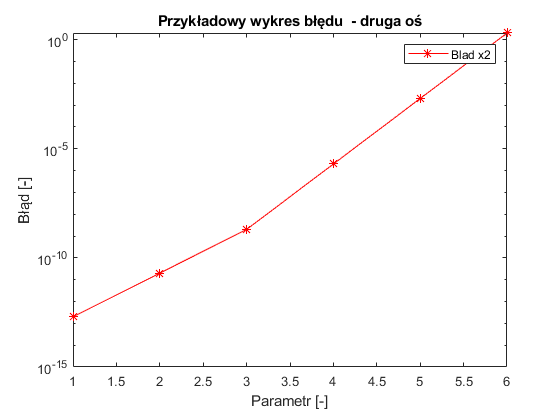


%yyaxis right
semilogy(x, mnoznik*blad, 'r*-');
legend(['Blad x' num2str(mnoznik)]);

grid off;
title('Przykładowy wykres błędu  - druga oś');
xlabel('Parametr [-]');
ylabel('Błąd [-]');


% Zwróć uwagę na:
% - przełącznik hold off zaraz po wybraniu okna (eliminuje poprzedni
% problem)
% - komendę tiledlayout i przełącznik nexttile
% - są to teraz dwie osobne osie więc każda z nich potrzebuje własnego
% tytułu, opisu osi i legendy

 

Warszawa, 27.02.2021 r.                                                                                                           **© **K. Król

Sem. 21L